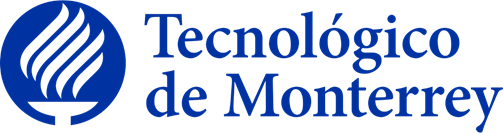

**Instituto Tecnológico y de Estudios Superiores de Monterrey**

TE3002B.502 

**Implementación de robótica Inteligente (Gpo 502)**

Semestre: febrero - junio 2023   

**Actividad:**

Evaluacion 7.1 Trayectorias en Lazo cerrado  

**Alumno:**

		José Angel Ramírez Ramírez   	A01735529

**Profesor: Dr. Alfredo Garcia Suarez.**

Fecha de entrega: 16 de Mayo del 2023

Se limpia la pantalla y el workspace


%Limpieza de pantalla
clear all
close all
clc


Se definen el tiempo final, el tiempo de muestreo y el vector de tiempo con base al tiempo final y el tiempo de muestreo. 

El tiempo final se obtiene por la suma de cada recorrido en linea recta que hace el robot mas cada giro. 

%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf=48.5;             % Tiempo de simulación en segundos (s)
ts=0.1;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras


%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Inicializamos las variables que se van a emplear
x1= zeros (1, N+1);       % Posición (X) en el centro del eje que une las ruedas en metros (m)
y1= zeros (1, N+1);       % Posición (Y) en el centro del eje que une las ruedas en metros (m)
phi= zeros (1, N+1);      % Orientación del robot en radiaanes (rad)


La posicion inicial del robot es indistinta, en este caso se puso en (-4, -1) para que el recorrido estuviera dentro de la grafica. 

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=-4;  %Posición inicial eje x
y1(1)=-1;  %Posición inicial eje y
phi(1)=0; %Angulo Inicial

%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Inicializamos el punto de control 
hx= zeros (1, N+1);       % Posición en el eje (X) del punto de control en metros (m)
hy= zeros (1, N+1);       % Posición en el eje (Y) del punto de control en metros (m)

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

v = 1*ones(1,N); % Velocidad lineal de referencia (m/s)
w = 0*ones(1,N); % Velocidad angular de referencia (rad/s)

En cada uno de los siguienes apartados, se modifican los vectores de velocidad para hacer los giros, en el caso del vector de velocidad lineal siempre se pone en 0, porque solo va a haber velocidad angular durante el giro. El vector de velocidades angulares solo se modifica con pi/2 o pi, esto es para hacer un giro de 90° o de 180° .

## letra J

v(11:20) = 0;
v(51:60) = 0; 
v(91:100) = 0; 

w(11:20) = pi/2; %90
w(51:60) = pi; %180
w(91:100) = pi/2; %90

%% letra O 
v(116:125) = 0; 
v(156:165) = 0; 
v(176:185) = 0;
v(216:225) = 0;

w(116:125) = pi/2;
w(156:165) = pi/2; 
w(176:185) = pi/2;
w(216:225) = pi/2;

%% Letra S
v(251:260) = 0;
v(276:285) = 0;
v(296:305) = 0;
v(321:330) = 0;

w(251:260) = pi/2;
w(276:285) = pi/2;
w(296:305) = -pi/2;
w(321:330) = -pi/2;

## Letra E

v(356:365) = 0;
v(376:385) = 0;
v(401:410) = 0;
v(421:430) = 0;
v(441:450) = 0;
v(466:475) = 0;

w(356:365) = pi;
w(376:385) = pi/2;
w(401:410) = pi/2;
w(421:430) = pi;
w(441:450) = pi/2;
w(466:475) = pi/2;


Finalmente solo se hace la simulacion

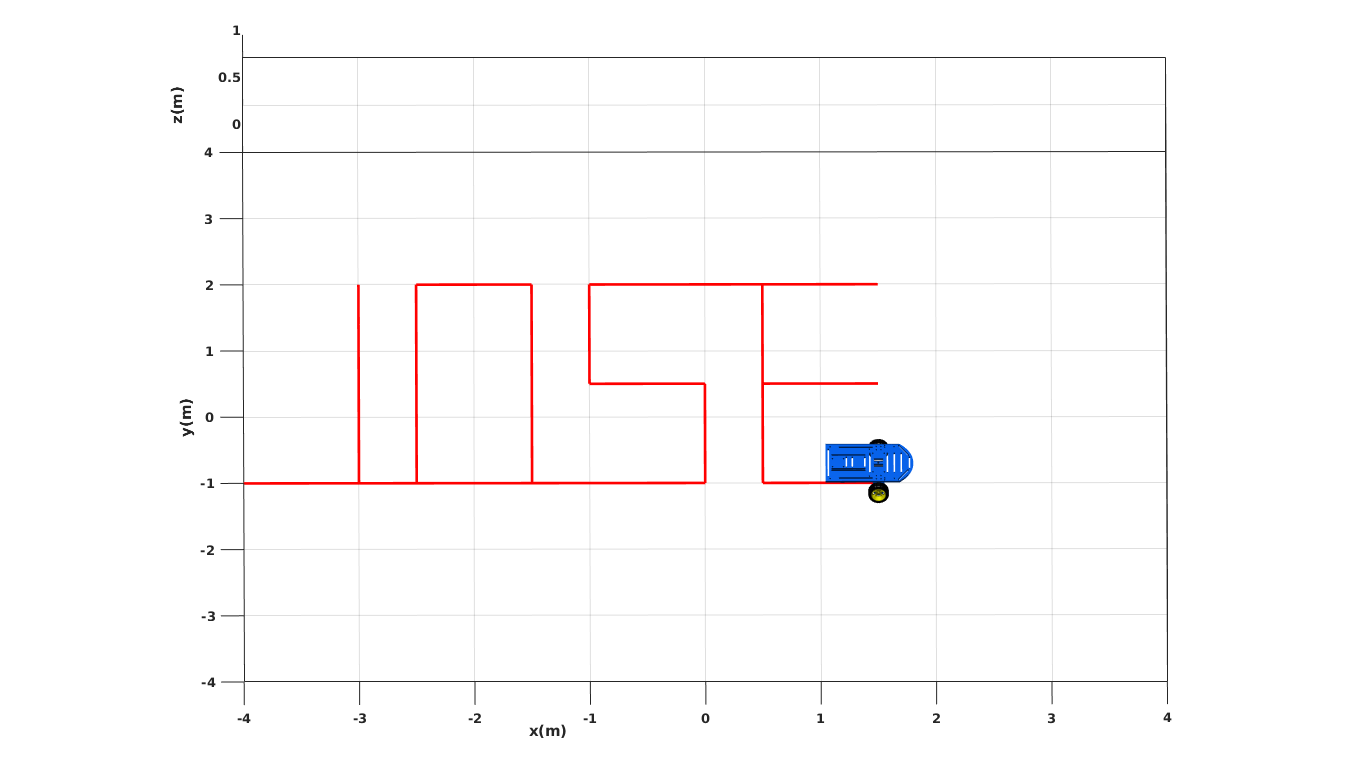



%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ ts*xp1; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ ts*yp1; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([-4 4 -4 4 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot;
H1=MobilePlot(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

## Preguntas

#### **a) **¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria recta? ¿Porqué?

     Para obtener una trayectoria recta, se debe modificar únicamente el vector de velocidad lineal, es decir, aumentar o disminuir la magnitud del vector v. Esto se          debe a que el vector de velocidad angular w es igual a cero en una trayectoria recta, ya que el robot no está girando sobre su propio eje.

#### **b)** ¿Cuál fué el o los parámetros que se modifican para obtener una trayectoria curva? ¿Porqué?

     Para obtener una trayectoria curva, se debe modificar tanto el vector de velocidad lineal como el vector de velocidad angular. La magnitud del vector v determinará la velocidad del robot a lo largo de la curva, mientras que la magnitud del vector w determinará la curvatura de la trayectoria. Cuanto mayor sea la magnitud del vector w, mayor será la curvatura de la trayectoria.

#### **c) **¿Cuál fué el o los parámetros que se modifican para obtener un giro? ¿Porqué?

    Para obtener un giro, se debe modificar únicamente el vector de velocidad angular, es decir, aumentar o disminuir su magnitud. En un giro, el vector de velocidad lineal es igual a cero, ya que el robot no se está moviendo en línea recta.

#### **d) **¿Qué papel desempeña el vector del tiempo en la generación de la trayectoria?

     El vector del tiempo es importante para la generación de la trayectoria ya que nos permite determinar la posición del robot en cada instante de tiempo. Conociendo la posición y orientación del robot en cada instante, podemos generar la trayectoria deseada. Por lo tanto, sin este no se podria generar la trayectoria. 

#### **e) **¿Cuáles fueron los parámetros que se ajustaron para obtener las dimensiones de las trayectorias deseadas?

    Para obtener los resultados se modificaron los siguientes 3 parametros.

- Vector de tiempo: Por cada metro que se deseara avanzar en linea recta  un metro o cada que se desaba hacer un giro, se añadio un segundo a este vector

- Vector de velocidad lineal: Como este vector se inicializo con 1's, se modificaron a 0's las muetras del segundo en el que se deseaba girar

- Vectori de velocidad angular: Este vector se inicializo en 0's por lo tanto se modificaron las mismas muestras del vector de velociad lineal, pero en este caso se modifico con el angulo que se deseaba girar, por ejemplo si se queria girar 90°, las muestras se modificaban con pi/2. 